## 平均音速値のモデルごとの比較

１：作成した各媒質のEMCL割合が一致しているのかの確認

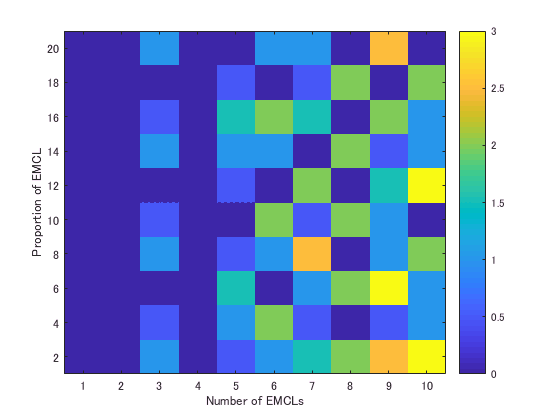

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_05_patternScatter2')
error_medium = zeros(10,10);
for i=2:2:20
    for j=1:10
        myfilename = sprintf('rEMCL%d & nEMCL%d',i,j);
        load(myfilename)
        error_medium(i/2,j) = abs(100*(sum(sum(medium.sound_speed == 1450)) / (numel(medium.sound_speed)*0.8))- i);
    end
end
figure; 
imagesc([1 2 3 4 5 6 7 8 9 10], [2 4 6 8 10 12 14 16 18 20],error_medium);
colorbar;
xlabel('Number of EMCLs')
ylabel('Proportion of EMCL')
set(gca,'YDir','normal');

２：誤差が0.1 %以上のものは使わないようにするためのlogical配列を作る．

usable = zeros(10,10);
for i = 2:2:20
    for j = 1:10
        usable(i/2,j) = (error_medium(i/2,j) < 0.1);
    end
end

３：全モデルでの平均音速値をプロットする．ここで構造の影響が大きく出ているデータを目視で特定する．ただし，媒質作成が誤差なく行われたものだけをプロットする．Number of EMCLs:1, 2, 4のみを用いる

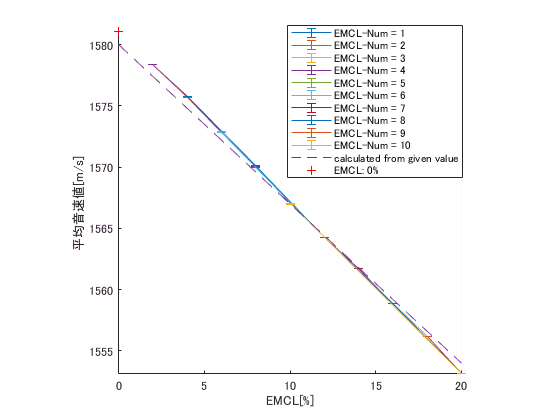

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_08_analyzePatternModel2')
load('2018_08_08_aveSOS&steSOS')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
figure;
hold on
x = [2 4 6 8 10 12 14 16 18 20];
x1 = [0 2 4 6 8 10 12 14 16 18 20];
for i = [1 2]
    errorbar(x, aveSOS(x,i), 2*steSOS(x,i));
%     legend(['EMCL-Num = ' num2str(i) ''])
end
x3 = [6 12 18];
errorbar(x3,aveSOS(x3,3),2*steSOS(x3,3));
errorbar(x, aveSOS(x,4), 2*steSOS(x,4));
x5 = [10 20];
errorbar(x5,aveSOS(x5,5),2*steSOS(x5,5));
x6 = [6 12 18];
errorbar(x6,aveSOS(x6,6),2*steSOS(x6,6));
x7 = 14;
errorbar(x7,aveSOS(x7,7),2*steSOS(x7,7));
x8 = [4 8 12 16 20];
errorbar(x8,aveSOS(x8,8),2*steSOS(x8,8));
x9 = 18;
errorbar(x9,aveSOS(x9,9),2*steSOS(x9,9));
x10 = [10 20];
errorbar(x10,aveSOS(x10,10),2*steSOS(x10,10));
plot(x1,v_muscle*(1-x1/100)+v_fat*x1/100,'--');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
load('2018_08_08_aveSOS&steSOS')
scatter(0,aveSOS,'r+');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
axis square
axis tight
xlim([0 20])
lgd = legend('EMCL-Num = 1','EMCL-Num = 2','EMCL-Num = 3','EMCL-Num = 4','EMCL-Num = 5',...
    'EMCL-Num = 6','EMCL-Num = 7','EMCL-Num = 8','EMCL-Num = 9','EMCL-Num = 10','calculated from given value','EMCL: 0%');
set(lgd,...
    'Position',[0.51261626409278 0.590538203810889 0.31428570763341 0.335714276347842]);

hold off

４：最速経路をとる素子ペアの関係

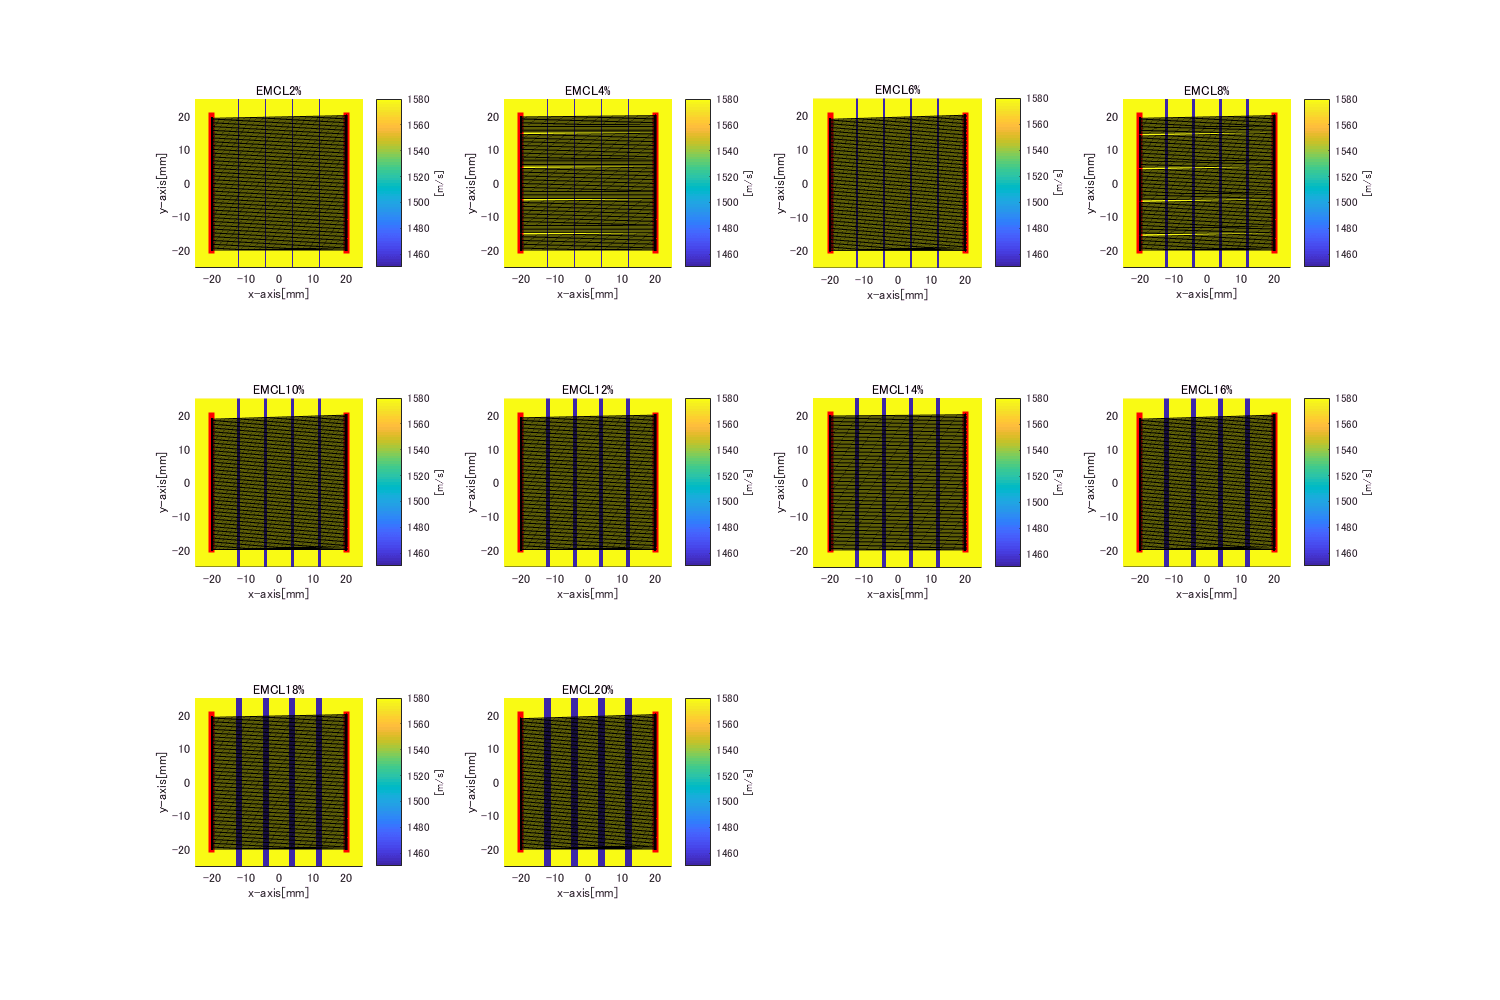

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_05_patternScatter2')
figure;
for i = 1:10
    myfilename = sprintf('rEMCL%d & nEMCL4',i*2);
    load(myfilename)
    subplot(3,4,i);
    hold on;
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
        axis equal
    axis tight
        scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    [~,ind] = min(tof_cell(101:end,:,2*i,4));
    ind = ind+100;
    for j = 1:length(ind)
        plot([t_pos(2,j)*1000;t_pos(2,ind(j))*1000],[t_pos(1,j)*1000;t_pos(1,ind(j))*1000],'.-k','LineWidth',0.01);
    end
    xlabel('x-axis[mm]')
    ylabel('y-axis[mm]')
    myfilename = sprintf('EMCL%d%%',i*2);
    title(myfilename);
    colorbar;
    caxis([1450 1580]);
    c = colorbar;
    c.Label.String = '[m/s]';
    hold off;
end
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_08_analyzePatternModel2\fastest_path_plot','png',[1500,1000]);

しきい